clc,clear
y = load('y.txt')   %把原始数据保存在纯文本文件 y.txt 中

y =          676         825         774         716         940        1159        1384        1524        1668        1688        1958        2031        2234        2566        2820        3006        3093        3277        3514        3770        4107


t = [1965:1:1985];
figure(1)
plot(t,y,'b*');
set(get(gca, 'Title'), 'String', '1965-1985年发电量 时间序列图');
m1=length(y);                 %计算y的长度（数量大小）
n=6;                          %n 为移动平均的项数  自行定义选择
for i=1:m1-n+1
    yhat1(i)=sum(y(i:i+n-1))/n;          %一次移动平均公式
end

yhat1      %一次移动平均的结果

yhat1 = 	1.0e+03 *

    0.8483    0.9663    1.0828    1.2318    1.3938    1.5635    1.7088    1.8505    2.0242    2.2162    2.4358    2.6250    2.8327    3.0460    3.2467    3.4612


m2=length(yhat1);
for i=1:m2-n+1
    yhat2(i)=sum(yhat1(i:i+n-1))/n;      %二次移动平均公式
end

yhat2   %二次移动平均的结果

yhat2 = 	1.0e+03 *

    1.1811    1.3245    1.4719    1.6288    1.7928    1.9665    2.1434    2.3307    2.5300    2.7337    2.9412


%计算平滑系数
a21=2*yhat1(end)-yhat2(end)   

a21 = 3.9811e+03

b21=2*(yhat1(end)-yhat2(end))/(n-1)

b21 = 207.9778

%预测1986 1987年的发电量 以1985年为基础,进行操作，
%第n年 yn= a21+(n-1985)*b21
y1986=a21+b21

y1986 = 4.1891e+03

y1987=a21+2*b21

y1987 = 4.3971e+03

y1988=a21+3*b21

y1988 = 4.6050e+03

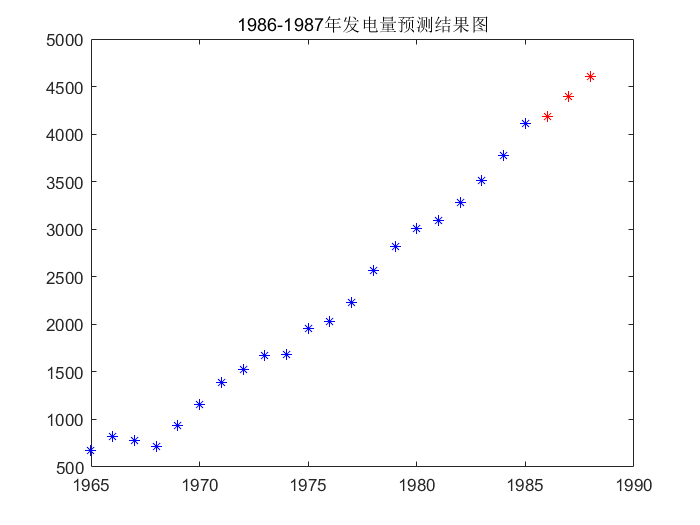

hold on

plot(1986,y1986,'r*',1987,y1987,'r*',1988,y1988,'r*');
title('1986-1987年发电量预测结果图')